# Gabriel Colangelo

clear
close all
clc

## Problem 2a-i)

Find: Wait time till the manuever (apogee)

% Given orbit parameters
rp          = 7000;         % [km]
ra          = 45000;        % [km]
mu_earth    = 398600.4415;  % [km^3/s^2] 

% Calculate semi major axis of old orbit
a           = (ra + rp)/2;  % [km]

% Calculate eccentricity of old orbit
e           = ra/a - 1;

% Calculate wait till manuever
dt          = pi/sqrt(mu_earth/a^3);
fprintf('The wait time till the manuever at apogee is %.2f hours',dt/3600)

The wait time till the manuever at apogee is 5.79 hours


$$M = \sqrt{\frac{\mu}{a^3}}(t - t_p) \\
\text{Currently at perigee. At apogee, M = $\pi$} \\
(t - t_p) = \frac{\pi}{ \sqrt{\frac{\mu}{a^3}}} \\
(t - t_p) = 5.8 \ [hours]
$$


## Problem 2a - ii)


$$\underline{Find}: \bar{r}_1, \bar{v}_1^-, \gamma_1^-, \bar{v}_1^+, \gamma_1^+ \ \text{for circularize at apogee}$$


% Calculate specific enegry of old orbit - pre manuever
energy      = -mu_earth/(2*a);

% Calculate speed at apogee - pre manuever
v1_m        = sqrt(2*(energy + mu_earth/ra));


$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r} \\ 
v_1^- = \sqrt{2(\epsilon + \frac{\mu}{r_a})} = 1.5443 \ [km/s]$$



$$\bar{r}_1 = 45000 \ \hat{r} \ [km] = -45000 \ \hat{e} \ [km] \\
\bar{v}_1^- = 1.5443 \ \hat{\theta}  \ [km/s] = -1.5443 \ \hat{p}  \ [km/s]$$


**Note:**** At apogee, the velocity vector is directly aligned in the **$\hat{\theta}$** direction which is aligned in the negative **$\hat{p}$** direction.**


$$\tan{\gamma} = \frac{v_r}{v_\theta} \\
\tan{\gamma^-_1} = 0\\
\gamma^-_1 = 0 \ [deg]$$


% Calculate circular velocity (circle with radius equal to distance to apogee) - post maneuver
v1_p        = sqrt(mu_earth/ra);

% Calculate new specific angular momentum - sami-latus rectum = radius for circle - post maneuver
h_p         = sqrt(mu_earth*ra);

% Calculate new flight path angle - post maneuver
gamma1_p    = acosd(h_p/(ra*v1_p));
fprintf('The flight path angle post maneuver is %.1f deg ', gamma1_p)

The flight path angle post maneuver is 0.0 deg 

**Note:**** For circular orbit, the semi-latus rectum is equal to the semi-major axis which equals the constant orbit radius.**


$$v_1^+ = \sqrt{\mu/r_1}  = 2.9762 \ [km/s]\\
h^+ = \sqrt{\mu p^+}  = r_1 v_1^+ \cos(\gamma_1^+) \\
\gamma_1^+ = \cos^{-1}{\frac{h^+}{r_1 v_1^+} \\
\gamma_1^+ = 0 \ [deg] \\
 \\

\bar{v}_1^+ = v_1^+\sin{\gamma_1^+} \ \hat{r} +  v_1^+\cos{\gamma_1^+} \ \hat{\theta}  \\
\bar{v}_1^+ = 2.9762 \  \hat{\theta} \ [km/s]$$



$$\Delta \bar{v} = \bar{v}_1^+ -  \bar{v}_1^-  = 1.4319 \ \hat{\theta} \ [km/s] \\ 
\Delta v = 1.4319 \ [km/s]$$



$$\underline{\textbf{No change in direction, $\alpha$ \ = 0}}$$


## Problem 2a - iii) Plot Orbits

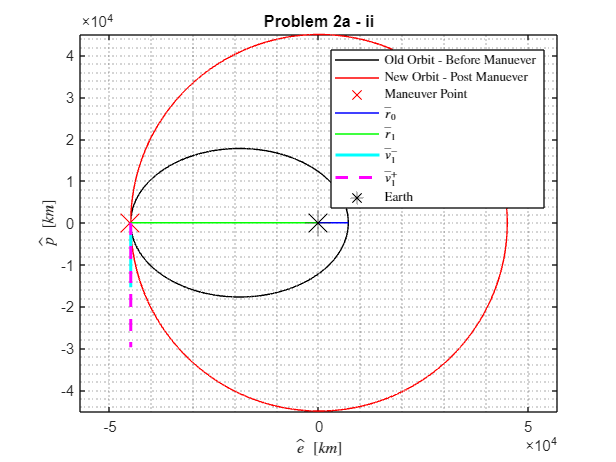

% True anomaly vector
ta_vec  = 0:.01:360;

% Semi-latus rectum of old orbit
p       = a*(1 - e^2);

% Initialize position vectors - in perifocal coordinates
r_P_old = zeros(2,length(ta_vec));
r_P_new = r_P_old;

for i = 1:length(ta_vec)

    % Calculate old orbit radii
    r_old           = p/(1 + e*cosd(ta_vec(i)));

    % DCM matrix from rotating orbit frame to perifocal frame
    P_DCM_R         = [cosd(ta_vec(i)), -sind(ta_vec(i));...
                       sind(ta_vec(i)), cosd(ta_vec(i))];
    
    % Rotate vectors from orbit frame to perifocal frame
    r_P_old(:,i)    = P_DCM_R*[r_old;0];
    r_P_new(:,i)    = P_DCM_R*[ra;0];
end

figure
plot(r_P_old(1,:), r_P_old(2,:),'-k')
hold on
plot(r_P_new(1,:), r_P_new(2,:),'-r')
plot(-ra, 0,'rx','MarkerSize',18)
plot([0 rp],[0 0],'-b')
plot([-ra 0],[0 0],'-g')
plot([-ra -ra],[0 -v1_m*10000],'-c','LineWidth',2)
plot([-ra -ra],[0 -v1_p*10000],'--m','LineWidth',2)
plot(0, 0,'k*','MarkerSize',18)
grid minor
xlabel('$\hat{e} \  [km]$', 'Interpreter','latex')
ylabel('$\hat{p} \ [km]$', 'Interpreter','latex')
axis equal
title('Problem 2a - ii')
legend('Old Orbit - Before Manuever','New Orbit - Post Manuever','Maneuver Point',...
       '$\bar{r}_0$','$\bar{r}_1$','$\bar{v}_1^-$','$\bar{v}_1^+$','Earth',...
       'Interpreter','latex','Location','best')

## Problem 2a - iv)

**100% of the maneuver magnitude is used to shift energy, as there is no change in direction for this maneuver, only a change in the shape of the orbit. **

## Problem 2b - i)

% New circular orbit radius
rc      = 25000;    % [km]

% True anomaly at maneuver location
ta_man  = acosd(((p/rc) - 1)/e);
fprintf('The true anomaly at the manuever location is %.3f deg (choose positive value)',ta_man)

The true anomaly at the manuever location is 134.851 deg (choose positive value)


$$r = \frac{p}{1 + e\cos{\theta^*}} \\
\theta^* = \pm \cos^{-1}{\frac{\frac{p}{r} - 1}{e}} \\
\theta^*  = 134.8 \ [deg]

$$


## Problem 2b - ii)

% Calculate eccentric anomaly at manuever location
E           = 2*atan2d(tand(ta_man/2),sqrt((1+e)/(1-e)));

% Calculate Mean anomaly at Orbit location
M           = E*pi/180 - e*sind(E);

% Wait time till manuever
dt2         = M/sqrt(mu_earth/a^3);
fprintf('The wait time till the manuever at apogee is %.2f hours',dt2/3600)

The wait time till the manuever at apogee is 1.45 hours


$$\tan({\frac{\theta^*}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E}{2}) \\

E = 2\tan^{-1}{[\tan({\frac{\theta^*}{2}) /\sqrt{\frac{1+e}{1-e}} ]} \\

M = E - e\sin{E} \\

M = \sqrt{\frac{\mu}{a^3}}(t - t_p) \\
\text{Currently at perigee} \\
(t - t_p) = \frac{M}{ \sqrt{\frac{\mu}{a^3}}} \\
(t - t_p) = 1.45 \ [hours]$$


## Problem 2b - iii) Plot Orbits


$$\underline{Find}: \bar{r}_1, \bar{v}_1^-, \gamma_1^-, \bar{v}_1^+, \gamma_1^+ \ \text{for circurlarizing manuever at 25000 km}$$


% Calculate speed at manuever point - pre manuever
v1_m2       = sqrt(2*(energy + mu_earth/rc));

% Specific angular momentum of old orbit
h           = sqrt(mu_earth*p);

% Calculate flight path angle - choose positive sign due to sign of true anomaly
gamma1_m    = acosd(h/(rc*v1_m2));
fprintf('The initial flight path angle is %.2f deg', gamma1_m)

The initial flight path angle is 46.91 deg


$$\epsilon = \frac{v^2}{2} - \frac{\mu}{r} \\ 
v_1^- = \sqrt{2(\epsilon + \frac{\mu}{r_1})} = 4.07 \ [km/s]$$



$$h^- = \sqrt{\mu p^-}  = r_1 v_1^- \cos(\gamma_1^-) \\
\gamma_1^- = \cos^{-1}{\frac{h^-}{r_1 v_1^-} \\
\gamma_1^- = 46.9 \ [deg] \ \text{Positive due to ascending based off of $\theta^*$} \\$$


% Velocity vector pre-manuever - rotate from orbit frame to perifocal
v1_m_O      = [v1_m2*sind(gamma1_m) ; v1_m2*cosd(gamma1_m)];
v1_m_P      = [cosd(ta_man), -sind(ta_man);...
               sind(ta_man), cosd(ta_man)]*v1_m_O;

% Position vector at manuever point
r1_P        = [cosd(ta_man), -sind(ta_man);...
               sind(ta_man), cosd(ta_man)]*[rc;0];


$$\bar{r}_1 = 25000 \ \hat{r} \ [km] = -17631.6 \ \hat{e} + 17723.6 \ \hat{p} \ [km] \\
\bar{v}_1^- =  2.97 \ \hat{r} +  2.78 \ \hat{\theta}  \ [km/s] = -4.06\ \hat{e} + 0.14 \ \hat{p}  \ [km/s]$$


% Calculate circular velocity (circle with radius equal to distance to apogee) - post maneuver
v1_p2       = sqrt(mu_earth/rc);

% Calculate new specific angular momentum - sami-latus rectum = radius for circle - post maneuver
h_p2        = sqrt(mu_earth*rc);

% Calculate new flight path angle - post maneuver
gamma1_p2   = acosd(h_p2/(rc*v1_p2));
fprintf('The flight path angle post maneuver is %.1f deg ', gamma1_p2)

The flight path angle post maneuver is 0.0 deg 

**Note:**** For circular orbit, the semi-latus rectum is equal to the semi-major axis which equals the constant orbit radius.**


$$v_1^+ = \sqrt{\mu/r_1}  = 3.99 \ [km/s]\\
h^+ = \sqrt{\mu p^+}  = r_1 v_1^+ \cos(\gamma_1^+) \\
\gamma_1^+ = \cos^{-1}{\frac{h^+}{r_1 v_1^+} \\
\gamma_1^+ = 0 \ [deg] \\$$


% Velocity vector in orbit frame - post manuever
v1_p_O      = [0;v1_p2];

% Rotate velocity vector into perifocal frame - post manuever
v1_p_P      = [cosd(ta_man), -sind(ta_man);...
               sind(ta_man), cosd(ta_man)]*v1_p_O;


$$\bar{v}_1^+ = v_1^+\sin{\gamma_1^+} \ \hat{r} +  v_1^+\cos{\gamma_1^+} \ \hat{\theta}  \\
\bar{v}_1^+ = 3.99 \  \hat{\theta} \ [km/s] = -2.83\ \hat{e} - 2.82\ \hat{p}  \ [km/s] \\
$$


% Calculate deltaV vector
dv_vec      = v1_p_O - v1_m_O;

% Calculate deltaV
dv          = sqrt(v1_p2^2 + v1_m2^2 - 2*v1_p2*v1_m2*cosd(gamma1_p - gamma1_m));
fprintf('The change in velocity magnitude is %.3f km/s', norm(dv_vec))

The change in velocity magnitude is 3.210 km/s


$$\Delta \bar{v} = \bar{v}_1^+ -  \bar{v}_1^- \\
\Delta \bar{v} =  -2.97\ \hat{r} + 1.21\ \hat{\theta}  \ [km/s] \\
\Delta v = |\Delta \bar{v}| = \sqrt{v_1^+ + v_1^- - 2v_1^+v_1^-\cos{\Delta \gamma}} = 3.2 \ [km/s]$$


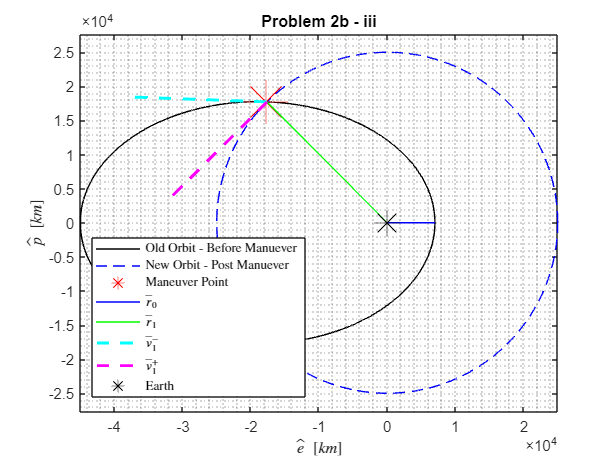

% Initialize position vectors - in perifocal coordinates
r_P_old = zeros(2,length(ta_vec));
r_P_new = r_P_old;

for i = 1:length(ta_vec)

    % Calculate old orbit radii
    r_old           = p/(1 + e*cosd(ta_vec(i)));

    % DCM matrix from rotating orbit frame to perifocal frame
    P_DCM_R         = [cosd(ta_vec(i)), -sind(ta_vec(i));...
                       sind(ta_vec(i)), cosd(ta_vec(i))];
    
    % Rotate vectors from orbit frame to perifocal frame
    r_P_old(:,i)    = P_DCM_R*[r_old;0];
    r_P_new(:,i)    = P_DCM_R*[rc;0];
end

figure
plot(r_P_old(1,:), r_P_old(2,:),'-k')
hold on
plot(r_P_new(1,:), r_P_new(2,:),'--b')
plot(r1_P(1), r1_P(2),'r*','MarkerSize',30)
plot([0 rp],[0 0],'-b')
plot([0 r1_P(1)],[0 r1_P(2)],'-g')
plot([r1_P(1) (r1_P(1)+ v1_m_P(1)*5000)],[r1_P(2) (r1_P(2) + v1_m_P(2)*5000)],'--c','LineWidth',2)
plot([r1_P(1) (r1_P(1)+ v1_p_P(1)*5000)],[r1_P(2) (r1_P(2) + v1_p_P(2)*5000)],'--m','LineWidth',2)
plot(0, 0,'k*','MarkerSize',18)
grid minor
xlabel('$\hat{e} \  [km]$', 'Interpreter','latex')
ylabel('$\hat{p} \ [km]$', 'Interpreter','latex')
axis equal
title('Problem 2b - iii')
legend('Old Orbit - Before Manuever','New Orbit - Post Manuever','Maneuver Point',...
       '$\bar{r}_0$','$\bar{r}_1$','$\bar{v}_1^-$','$\bar{v}_1^+$','Earth',...
       'Interpreter','latex','Location','best')